clear all
close all
% 假設檔案在同一個資料夾內
fileList = dir('*.txt'); % 選取當前資料夾下的所有 txt 檔案
data = []; % 用來儲存所有檔案的數據
time = []; % 用來儲存時間的數據
filen = length(fileList);

for j = 1:filen    
    try
        % 讀取每個檔案
        filename = fileList(j).name;
        fileID = fopen(filename, 'r');
        % 讀取檔案內容，並忽略空行
        fileData = textscan(fileID, '%s %f %f %f %f %f %f %f %f %f %f', 'Delimiter', '\t');
        
        % 關閉檔案
        fclose(fileID);
        
        % 提取檔名中的日期
        dateStr = extractBetween(filename, 'logger_', '_'); % 提取日期部分
        date = datetime(char(dateStr), 'InputFormat', 'yyyyMMdd'); % 根據檔名格式創建日期物件
    
        % 將日期與時間結合
        fullTime = strcat(repmat(string(date), length(fileData{1}), 1), '-', fileData{1}); % 將日期與時間字串結合
        fullTime = datetime(fullTime, 'InputFormat', 'dd-MMM-yyyy-HH:mm:ss.SS'); % 創建完整的日期時間物件
        time = [time; fullTime]; % 加入到時間陣列
    
        data = [data; fileData{2:end}]; % 跳過第一欄時間戳，加入其他數據    
    catch
        fprintf('檔案 %s 的資料格式錯誤，已跳過。\n', filename);
    end
end

檔案 logger_20240923_165010.txt 的資料格式錯誤，已跳過。
檔案 logger_20240923_172808.txt 的資料格式錯誤，已跳過。



time = time(~isnat(time)); % 刪除 NaT 值
data(end,:)=[];
data(end,:)=[];
[n,~]=size(data);

acc = data(:, 1:3);
lat = data(:, 4);
lon = data(:, 5);
alt = data(:, 6);
gps = data(:, 7);
tem = data(:, 8);
v = data(:, 9);
i = data(:, 10);

for j=1:n
    if(i(j)==0)
        i(j)=NaN;
    end
end


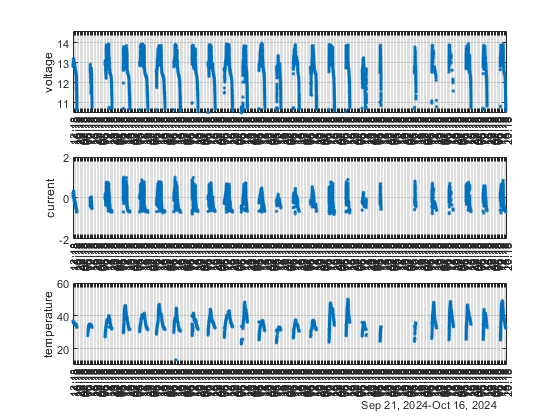

close all

figure(1);
subplot(3,1,1)
plot(time,v, '.');
ylabel('voltage')
ylim([10.5 14.6])
grid on;
xticks(time(1):hours(2):time(end)+0.1); % 設定 x 軸的刻度
datetick('x', 'HH:MM', 'keepticks'); % 格式化 x 軸標籤

subplot(3,1,2)
plot(time,i, '.');
ylabel('current')
ylim([-2 2])
grid on;
xticks(time(1):hours(2):time(end)+0.1);
datetick('x', 'HH:MM', 'keepticks');

subplot(3,1,3)
plot(time,tem, '.');
ylabel('temperature')
ylim([10 60])
grid on;
xticks(time(1):hours(2):time(end)+0.1);
datetick('x', 'HH:MM', 'keepticks');
xtickformat('HH:mm'); % 顯示時間

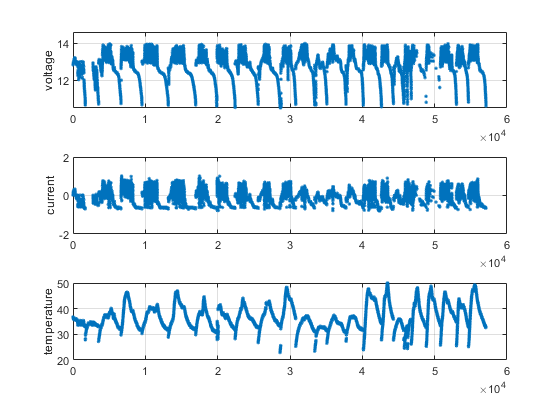



figure(2);
subplot(3,1,1)
plot(v, '.');
ylabel('voltage')
ylim([10.5 14.6])
grid on;
subplot(3,1,2)
plot(i, '.');
ylabel('current')
ylim([-2 2])
grid on;
subplot(3,1,3)
plot(tem, '.');
ylabel('temperature')
ylim([20 50])
grid on;

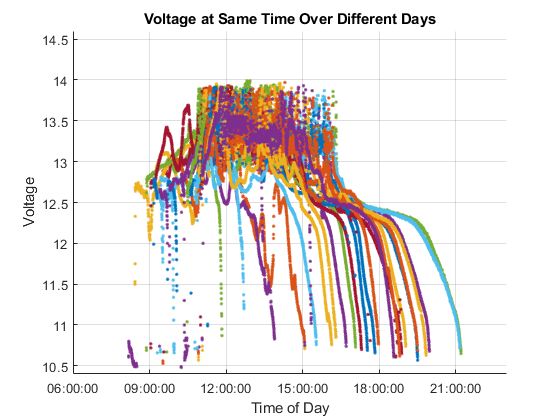

close all

% 只保留時間部分，用於疊加每日同一時間
timeOnly = timeofday(time);

% 建立新圖，用於繪製每日同時間的電壓
figure(3);
hold on;
days = unique(dateshift(time, 'start', 'day')); % 找出所有日期

% 將每個日期的數據疊加到同一圖上
for d = 1:length(days)
    dayIndices = (dateshift(time, 'start', 'day') == days(d));
    plot(timeOnly(dayIndices), v(dayIndices), '.');
end

xlim([hours(6) hours(23)]); % x 軸設定為從 6 點到 22 點
xlabel('Time of Day');
ylabel('Voltage');
title('Voltage at Same Time Over Different Days');
ylim([10.4 14.6])
grid on;
% datetick('x', 'HH:MM', 'keepticks');
% xtickformat('HH:mm'); % 格式化 x 軸時間顯示
hold off;

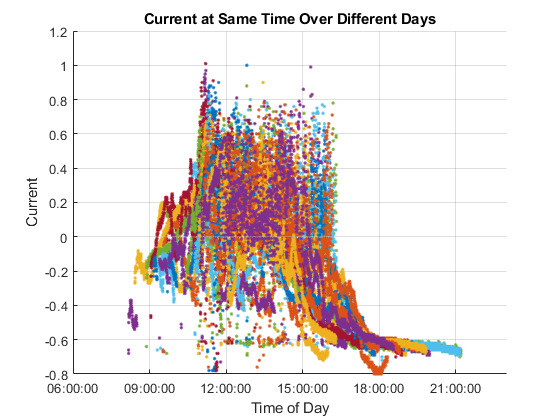


% 建立新圖，用於繪製每日同時間的電壓
figure(4);
hold on;
days = unique(dateshift(time, 'start', 'day')); % 找出所有日期

% 將每個日期的數據疊加到同一圖上
for d = 1:length(days)
    dayIndices = (dateshift(time, 'start', 'day') == days(d));
    plot(timeOnly(dayIndices), i(dayIndices), '.');
end

xlim([hours(6) hours(23)]); % x 軸設定為從 6 點到 22 點
xlabel('Time of Day');
ylabel('Current');
title('Current at Same Time Over Different Days');
% ylim([10.4 14.6])
grid on;
% datetick('x', 'HH:MM', 'keepticks');
% xtickformat('HH:mm'); % 格式化 x 軸時間顯示
hold off;

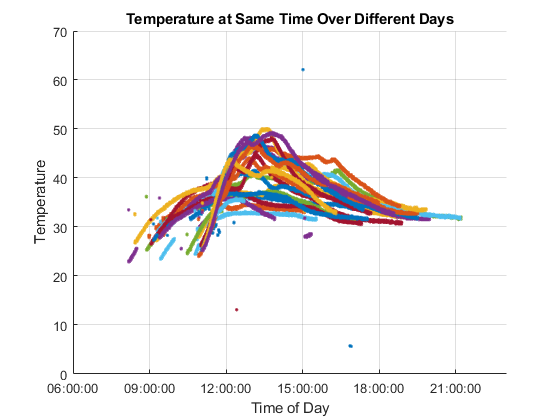


% 建立新圖，用於繪製每日同時間的電壓
figure(5);
hold on;
days = unique(dateshift(time, 'start', 'day')); % 找出所有日期

% 將每個日期的數據疊加到同一圖上
for d = 1:length(days)
    dayIndices = (dateshift(time, 'start', 'day') == days(d));
    plot(timeOnly(dayIndices), tem(dayIndices), '.');
end

xlim([hours(6) hours(23)]); % x 軸設定為從 6 點到 22 點
xlabel('Time of Day');
ylabel('Temperature');
title('Temperature at Same Time Over Different Days');
% ylim([10.4 14.6])
grid on;
% datetick('x', 'HH:MM', 'keepticks');
% xtickformat('HH:mm'); % 格式化 x 軸時間顯示
hold off;